data_pca = data_pca(574:884, :);
data_pca = rmmissing(data_pca);
% Extract the label and training data set.
label_pca = data_pca(:, 1);
training_pca = data_pca(:, 2:end);

% Train PCA model
[coeff,score,latent] = pca(training_pca);
variance_proportion = cumsum(latent/sum(latent));
disp(variance_proportion);

    0.9999
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000



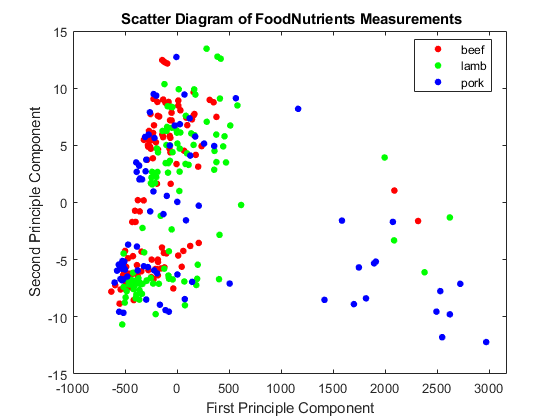

% Plot the data in the space spanned by the first two principal 
% components. Colour each point by its class.
score2 = score(:, 1:2);
figure
gscatter(score2(:, 1), score2(:,2), label_pca);
ax = gca; % current axes
lims = [ax.XLim ax.YLim]; % Extract the x and y axis limits
title('{\bf Scatter Diagram of FoodNutrients Measurements}');
xlabel('First Principle Component');
ylabel('Second Principle Component');
legend('beef', 'lamb','pork');